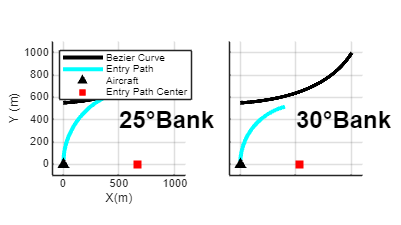

clc; clear; close all;
t = 0:0.001:1;
format short;
P0 = [0, 550];
P1 = [750, 600];
P2 = [1000, 1000];

bx = P1(1) + (P0(1)-P1(1))*(1-t).^2 + (P2(1)-P1(1))*t.^2;
by = P1(2) + (P0(2)-P1(2))*(1-t).^2 + (P2(2)-P1(2))*t.^2;

ba = deg2rad(24.789);
tr = 106.5227^2  / (11.26*tan(ba));
tr = tr*0.3048;
h = tr;
k = 0;
x = 0:0.01:bx(298);
cy = k + sqrt(tr^2 - (x-h).^2);

box('on')
ax = gca;
% ax.FontWeight = 'bold';
% % ax.FontName = 'Times';
set(gcf, 'Position', [700 350 1250 700])

subplot(1, 2, 1)
hold on;
plot(bx, by, color = 'black', LineWidth=3)
% scatter(P0(1), P0(2), MarkerEdgeColor = 'blue');
% scatter(P1(1), P1(2), MarkerEdgeColor = 'blue');
% scatter(P2(1), P2(2), MarkerEdgeColor = 'blue');
plot(x, cy, color = 'cyan', LineWidth=3)
scatter(0, 0, Marker='^', MarkerFaceColor='black', MarkerEdgeColor='black', SizeData= 50)
scatter(h, k, Marker = 's', MarkerEdgeColor='red', MarkerFaceColor='red', SizeData=50)
grid('on')
axis('equal')
xlabel('X(m)')
ylabel('Y (m)')
ylim([-100, 1100]);
xlim([-100, 1100]);
text(500, 400, ['25' char(176) 'Bank'], fontsize = 18 , FontWeight= 'bold')
legend('Bezier Curve', 'Entry Path', 'Aircraft', 'Entry Path Center')
legend('Location', 'northwest')
hold off;

ba = deg2rad(30);
tr = 106.5227^2  / (11.26*tan(ba));
tr = tr*0.3048;
h = tr;
k = 0;
x = 0:0.01:bx(298);
cy = k + sqrt(tr^2 - (x-h).^2);

subplot(1, 2, 2)
hold on;
plot(bx, by, color = 'black', LineWidth=3)
% scatter(P0(1), P0(2), MarkerEdgeColor = 'blue');
% scatter(P1(1), P1(2), MarkerEdgeColor = 'blue');
% scatter(P2(1), P2(2), MarkerEdgeColor = 'blue');
plot(x, cy, color = 'cyan', LineWidth=3)
scatter(0, 0, Marker='^', MarkerFaceColor='black', MarkerEdgeColor='black', SizeData= 50)
scatter(h, k, Marker = 's', MarkerEdgeColor='red', MarkerFaceColor='red', SizeData=50)

grid('on')
axis('equal')
% xlabel('X(m)')
% ylabel('Y (m)')
ylim([-100, 1100]);
text(500, 400, ['30' char(176) 'Bank'], fontsize = 18 , FontWeight= 'bold')
xlim([-100, 1100]);
set(gca, 'XTickLabel', [], 'YTickLabel', []);